# Authors: Marta Barriendos & Ana Garcia Armada, Univesidad Carlos III de Madrid

# SIMULATION OF OFDM WITH MATLAB

## Introduction

This second live script is focused on tailoring the previous implementation for the case of LTE (4G) and 5G.

## Index

- OFDM basics and implementation, frame structure, guards and cyclic prefix.

- LTE (4G) Particularization.

- 5G Particularization.

- Channel effects and their estimation and compesation for OFDM. 

## 2. LTE PARTICULARIZATION

The idea in this section is to repeat the process made before, but in this case, particularizing our parameters for the LTE case. As we can see in the next table, the example we did above was the one of 20 MHz (on the right side of the table), now the LTE case corresponds to 10 MHz, as it is marked in the table. 

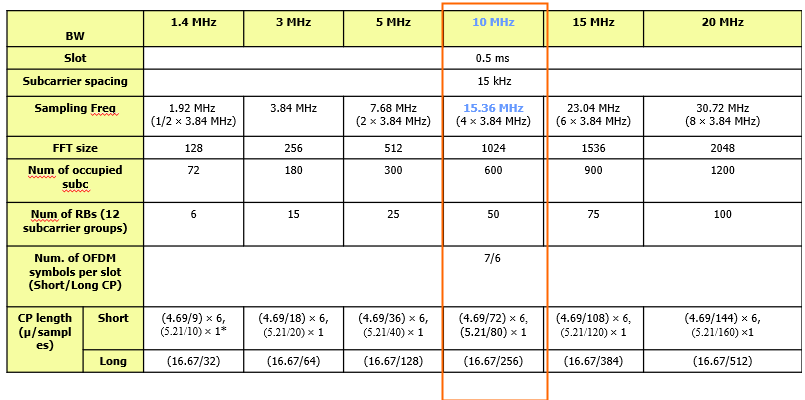

This means that now, we have as total subcarriers *N_OFDM=1024 *(instead of 2048), and as occupied subcarriers *Nu=600. *The substraction between them is the number of zero subcarriers (or guard bands) fg=N_OFDM-Nu=424, which means that half of that subcarriers will be placed at the initial part of the symbol, and the other half will be placed at the final part (*fg_1* and* fg_2 *respectively). The next parameter is the cyclic prefix, which for the case of LTE standard we have 2 prefixes defined, *Ng1=80 *(longest one) and *Ng2=72* (shortest one), which enhances the sincronization and provides a better protection against multipath. Then, since in LTE,  a subframe consists of 7 OFDM symbols per slot (with normal cyclic prefix), resulting in a total of 14 OFDM symbols per subframe (because a subframe contains 2 slots), we can calculate the average size of the cyclic prefix (Ngav) taking into consideration that the longest prefix is only used for the first symbol of the frame, and the shortest one is used in the other 6 symbols. Another interesing parameters are, the number of pilots, which is again 45, *num_pilots=45*, the sampling frequency, in this case *Fs=15.36 MHz*, and the amplitude of the pilots, which is again 1 (*P_ampl*). 

Finally, it is important to reflect the fact that the next examples (LTE and 5G), have been made without considering the pilots, because for these standars they are not equally distributed. 

N_OFDM=1024;
Nu=600;
fg=N_OFDM-Nu;
fg_1=floor(fg/2);
fg_2=fg_1;

Ng2=72;
Ng1=80;
Ngav=(Ng1*6+Ng2)/7;

Fs=15.36;

Now, following the same steps as before, we can calculate the effective number of subcarriers (*N_OFDM_ef)*, the number of symbols we are going to simulate (*N_symb*), and the total number of samples (*n_samples*).

N_OFDM_ef=N_OFDM-fg_1-fg_2;
N_symb=7; 
n_samples=N_symb.*N_OFDM_ef; 
fprintf('Number of subcarriers for guard bands: %f, %f  1/%f\n',fg_1,fg_2,N_OFDM/Ngav);

Number of subcarriers for guard bands: 212.000000, 212.000000  1/12.985507


We already have everything prepared to create the OFDM signal. For doing this process, first we must create a zero vector with the proper dimensions, so, since the number of symbols we want to simulate is 7 (*N_symb), *and we have explained that each frame has this 7 symbols, from which the first one uses the longest prefix (*Ng1*) and the 6 others (*N_symb-1*) the shortest one, this must be taken into consideration when specifying the total length for our signal (*signal*). Therefore, each symbol has *N_OFDM* total subcarriers (including both the effective ones and the guard bands) plus the number chosen for the cyclic prefix (*Ng1 *if it's the first symbol or *Ng2* for the other 6 symbols):

signal=zeros(1,(N_OFDM+Ng1)+(N_symb-1)*(N_OFDM+Ng2));

The next step is to fill the zero signal created above. So, firstly, for each one of the symbols we want to simulate, in this case for the 7 symbols of the frame, we need to generate a QPSK sequence in base band (*qpsk*). Secondly, we create an additional qpsk signal (*qpsk_ini*), with zero in all de *N_OFDM* positions, and we add the *qpsk* sequence created before, between the guard bands. At this point, we already have the transmission signal created (*qpsk_ini*) with all the subcarriers, including the guard bands, modulated with QPSK. So now, we can create the OFDM signal applying the IFFT and normalizing the result multipying by the factor  *N_OFDM, *getting in this way the first *ofdm* signal. Now, we need to add the cyclic prefix, which changes a bit compared with the previous example, because now, we have 2 different prefixes, *Ng1* and *Ng2*. Therefore, first we must determine which prefix to apply, depending on if we are working with the first symbol of the frame, then we'll use the long prefix *Ng1*, or if we're working with the other 6 symbols, then we'll apply the short prefix, *Ng2*. For doing this selection, we are using the *if else* structure presented in the code. Once we have saved in *Ng*, the prefix we want to use, we just have to repeat the steps of the previous example. We are rewriting the same signal *ofdm *adding to the initial part the proper prefix chosen, that as we have previously explained, consists of the last *Ng* subcarriers. Finally, the last step requires filling the general zero signal created before (*signal*), with the OFDM signal (*ofdm*) calculated in the loop, for each simulated symbol (*symb*), in its proper position.

for (symb=1:N_symb)   
  
    i=sign(rand(1,N_OFDM_ef)-0.5);
    q=sign(rand(1,N_OFDM_ef)-0.5);
    qpsk=i+j*q;


    qpsk_ini=zeros(1,N_OFDM);
    qpsk_ini(fg_1+1:N_OFDM-fg_2)=qpsk;
  

    ofdm=N_OFDM.*ifft(qpsk_ini,N_OFDM);

    if symb==1,
        Ng=Ng1;
    else
        Ng=Ng2;
    end

    ofdm=[ofdm(N_OFDM-Ng+1:N_OFDM),ofdm];
    
    signal(1,(symb-1)*(N_OFDM+Ng)+1:symb*(N_OFDM+Ng))=ofdm;
    

end 

Finally, once we have the signal created, we can represent its spectrum, corresponding to the LTE standard, to verify that the OFDM signal that we have generated looks great. 

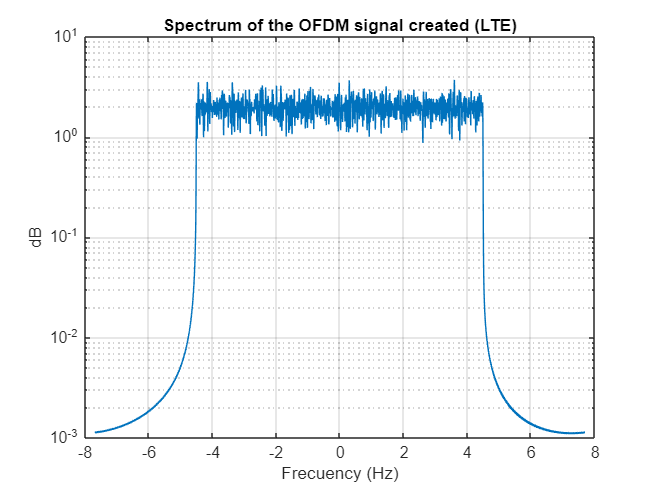

[p,f] = pspectrum(signal);
new_f=f./pi*Fs/2;
figure
semilogy(new_f,fftshift(p))
grid on
title('Spectrum of the OFDM signal created (LTE)')
xlabel("Frecuency (Hz)")
ylabel('dB')

Now, let's verify that what we have generated is correct. As we were expecting from the previous table ( *Fs= 10 MHz*), the total bandwidth is almost 10 MHz. But, if we look at the used bandwidth, in the graph we can see how it comprends the range from -4.48 MHz to 4.48 MHz, which means that the used bandwidth we have obtained is aproximately 8.96 MHz, then we have as guard bands,$10\;\textrm{MHz}-8\ldotp 96\;\textrm{MHz}=1\ldotp 04\;\textrm{MHz}$. So let's see if this is what we were expecting from the theoretical background. 

From the previous table, we know that the number of occupied subcarriers is 600, and the subcarriers spacing is $\Delta f=$15 kHz, this means that the used bandwidth is, $\textrm{BW}=600\times \Delta f=9\;\textrm{MHz}$, which is aproximately equal to the practical bandwidth we have obtained above (8.96 MHz).

Therefore, it is clear that the result we have obtained from the simulation is correct. 

To finish this section, we can represent the OFDM signal obtained before, in the time domain, and then, remark in red the time instants corresponding to 7 the symbols we are sending. 

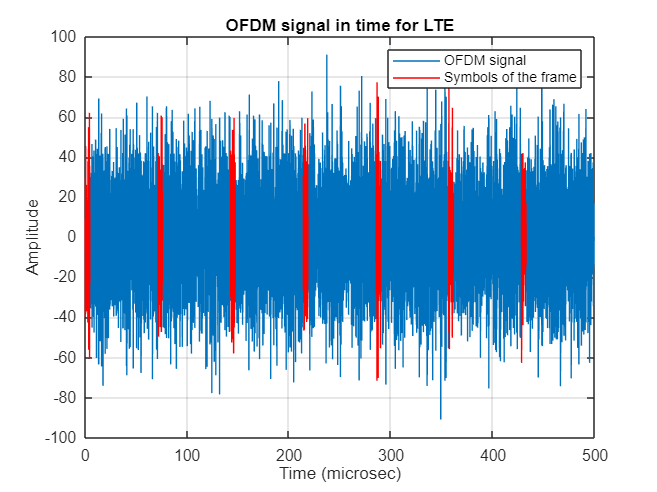

figure
time=(0:1/Fs:((N_OFDM+Ng1)+(N_symb-1)*(N_OFDM+Ng2))/Fs-1/Fs); 
plot(time,real(signal))
hold on
for (symb=1:N_symb)   
    plot( time( (symb-1)*(N_OFDM+Ng)+1:Ng+(symb-1)*(N_OFDM+Ng) ),real( signal( (symb-1)*(N_OFDM+Ng)+1:Ng+(symb-1)*(N_OFDM+Ng) ) ),'r')
end
grid on
xlabel('Time (microsec)')
ylabel('Amplitude')
title('OFDM signal in time for LTE')
legend('OFDM signal','Symbols of the frame')

Analyzing the previous graph, it is clear that the duration of the 7 symbols we have sent is 0.5 miliseconds, which is exactly what we were expecting from the LTE standard, so our representation looks great. 

## 3. 5G PARTICULARIZATION

In this third section, we are going to particularize the OFDM signal for the 5G case. The implementation and variables are the same as in the previous example of LTE, but the initial parameters, as we can see below, have different values. We are going to continue with a value for the bandwidth of 15.36 MHz (*Fs*), like before for LTE. However, in this case, we are using a total number of subcarriers equal to 512 (*N_OFDM*), and a number of util subcarriers of 288 (*Nu*), the substraction between them will correspond to the guard bands (*fg*). For the cyclic prefix, the initial parameters are also different, we are using a long prefix of 40 samples (*Ng1*), and a short prefix of 36 subcarriers (*Ng2*). For calculating the average prefix, we consider, as in LTE, that each frame has 7 symbols, from which, the first one will use the longest prefix, and the other 6 will use the shortest prefix, obtaining in this way the average value *Ngav*. Finally, regarding the pilots, we aren't considering them, like in the previous example for LTE. 

In the 5G standard, we have the *numerology*, which refers to the subcarrier spacing. For this standard, the spacing can be variable. In this example, considering that our bandwidth is 15.36 MHz and that we are using 512 subcarriers, we have a spacing of 30 KHz. If we compare it with the previous case of LTE, where we had 1024 subcarriers, in this case, we have half the number of subcarriers, which means that we are doubling the frequency spacing between carriers. By doubling the frequency spacing between carriers, within the same bandwidth as LTE, we send half the number of subcarriers. Therefore, if we double the frequency spacing, we reduce the time spacing by half, so now, in 0.5 milliseconds, we send twice the number of symbols, 14 instead of 7, we'll see this in the next graphs. This also happens with the cyclic prefix, the new duration is going to be half the duration of the LTE case (36 instead of 72 for *Ng2*, and 40 instead of 80 for *Ng1*)

Fs=15.36;
N_OFDM=512;
Nu=24*12;

fg=N_OFDM-Nu;
fg_1=floor(fg/2);
fg_2=fg_1;

Ng2=36; 
Ng1=40;
Ngav=(Ng1*6+Ng2)/7;


Once we have all the parameters stablished, we can do the necessary operations to get the number of efficient subcarriers (N_OFDM_ef), which means the number of data subcarriers. In this case, we decide to simultate 14 OFDM symbols (*N_symb*), instead of 7 symbols like we were doing for LTE, since the symbol duration is half the one we had in LTE. With this information, we can already calculate the number of real samples of our simulation (n_samples).

N_OFDM_ef=N_OFDM-fg_1-fg_2;
N_symb=14; 
n_samples=N_symb.*N_OFDM_ef; 
fprintf('Guard bands: %f, %f  1/%f\n',fg_1,fg_2,N_OFDM/Ngav); %La fracción sale igual

Guard bands: 112.000000, 112.000000  1/12.985507


Now we have everything we need to create the OFDM signal. For doing this process, like before, first we have to create a zero vector with the proper dimensions. In this case, we have assume the same situation as for LTE,  meaning that each frame has this 7 symbols, from which the first one uses the longest prefix (*Ng1*) and the 6 others (*N_symb-1*) the shortest one. Therefore, each symbol has *N_OFDM* total subcarriers (including both the effective ones and the guard bands) plus the number chosen for the cyclic prefix (*Ng1 *if it's the first symbol or *Ng2* for the other 6 symbols):

signal=zeros(1,(N_OFDM+Ng1)+(N_symb-1)*(N_OFDM+Ng2));

The next step is to fill the zero signal with the proper values, considering symbols modulated with QPSK. We can see in the code below how are we doing this process, verifying how it is exaclty the same as for the LTE example. 

for (symb=1:N_symb)   

    i=sign(rand(1,N_OFDM_ef)-0.5);
    q=sign(rand(1,N_OFDM_ef)-0.5);
    qpsk=i+j*q;


    qpsk_ini=zeros(1,N_OFDM);
    qpsk_ini(fg_1+1:N_OFDM-fg_2)=qpsk;

    ofdm=N_OFDM.*ifft(qpsk_ini,N_OFDM);

    if symb==1
        Ng=Ng1;
    else
        Ng=Ng2;
    end

    ofdm=[ofdm(N_OFDM-Ng+1:N_OFDM),ofdm];
    
    signal(1,(symb-1)*(N_OFDM+Ng)+1:symb*(N_OFDM+Ng))=ofdm;

end

Finally, once we have the signal created, it is interesting to represent the spectrum of our new 5G signal. We can verify how it is very similar to the LTE case, but the spectrum in 5G case has wider tails, is more noisy.

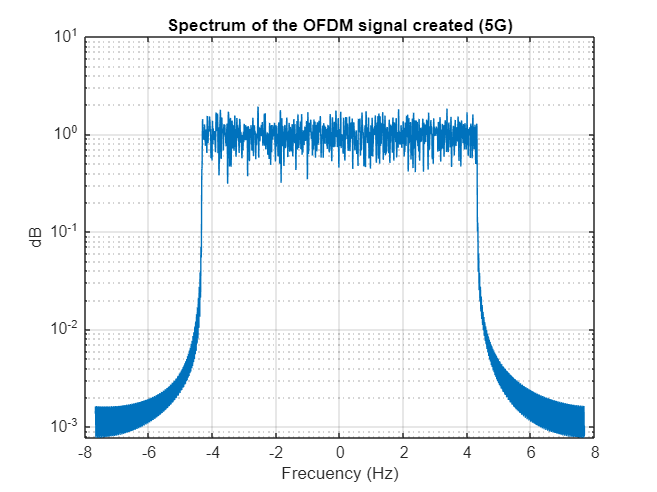

[p,f] = pspectrum(signal);
new_f=f./pi*Fs/2;
figure
semilogy(new_f,fftshift(p))
grid on
title('Spectrum of the OFDM signal created (5G)')
xlabel("Frecuency (Hz)")
ylabel('dB')

Regarding the graph above, let's remember, we have exactly the same bandwidth, but, a different name of subcarriers than in the LTE case. We have doubled the space between subcarriers, and therefore, we have half the number of LTE subcarriers. 

Now, let's make the representation in the time domain. As we can see in the graph below, it is very similar to the LTE one, but, since in this case we are simulating 14 symbols, we can see remaked in red, the time instants where these symbols appear in the OFDM signal. 

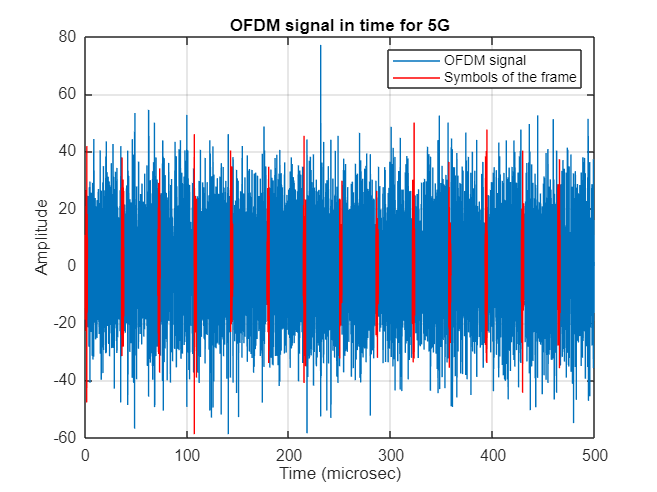

figure
time=(0:1/Fs:((N_OFDM+Ng1)+(N_symb-1)*(N_OFDM+Ng2))/Fs-1/Fs); 
plot(time,real(signal))
hold on
for (symb=1:N_symb),   
plot( time( (symb-1)*(N_OFDM+Ng)+1:Ng+(symb-1)*(N_OFDM+Ng) ),real( signal( (symb-1)*(N_OFDM+Ng)+1:Ng+(symb-1)*(N_OFDM+Ng) ) ),'r')
end
grid on
xlabel('Time (microsec)')
ylabel('Amplitude')
title('OFDM signal in time for 5G')
legend('OFDM signal','Symbols of the frame')

Analyzing this last graph, we can see exactly what we had explained at the begining of this 5G section. Since the OFDM symbol duration now is half the duration than in LTE, in the same time (0.5 miliseconds), we are sending the double of symbols, 14 instead of 7. Therefore, the signal duration is the same, but the number of symbols is higher. 